## **CSC 482 Applied Image Analysis**

## **Assignment 4**

## **Name: Pooja Venugopal Baskaran**

## **Student ID: 2172642**

## **Date: 02/23/2025**

**A. Detecting edges (10 points)**

**Use the edge function in Matlab (or image library in your language of preference) instead of implementing your own. Use the help function to read more about the edge function. The syntax in Matlab is BW = edge(I, 'canny', thresh, sigma), where thresh is a 1x2 matrix with high and low threshold. Sigma is the standard deviation of the Gaussian filter. Open the image 'house.tif' and display it.**

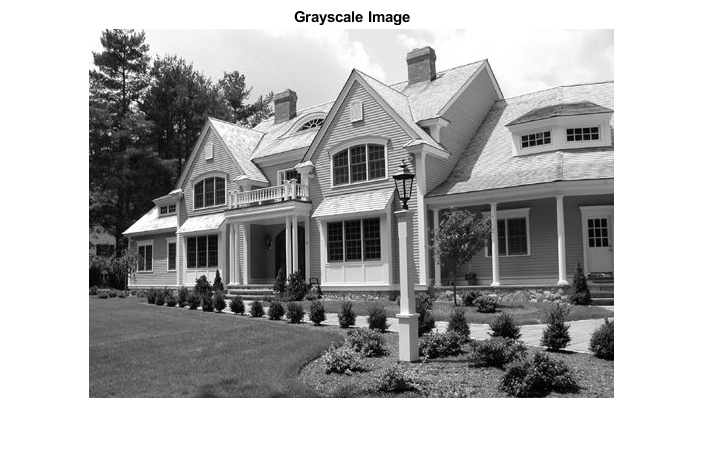

Img = imread('C:\\Users\\PVENUGO1\\Downloads\\APPLIED IMAGE ANALYSIS - 2222025 - 1125 PM\\house.jpg');
if size(Img,3) == 3
    Img = rgb2gray(Img);
end
figure, imshow(Img), title('Grayscale Image');

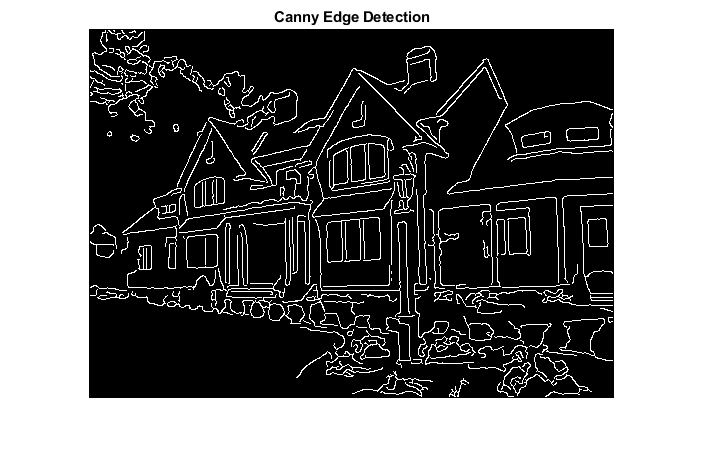

sigma = 01.5;
thresh = [0.1 0.3];
BW = edge(Img, 'canny', thresh, sigma);
figure, imshow(BW), title('Canny Edge Detection');

**a) What is your opinion on what an edge is in this particular image?**

A edge in the image here represents the significant change in pixels in the image.

**b) Now your task is to adjust the Canny input parameters to detect the “best” set of**

**edges that you can.**

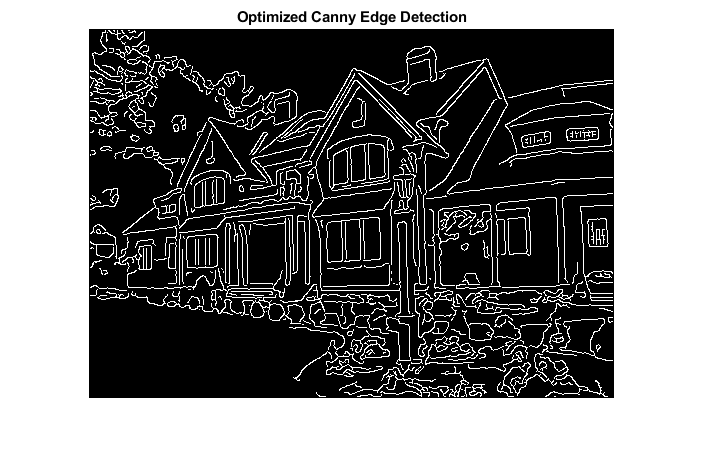

sigma_1 = 1.5; 
thresh_1 = [0.05 0.2];  
BW_1 = edge(Img, 'canny', thresh_1, sigma_1);
figure, imshow(BW_1), title('Optimized Canny Edge Detection');

**B. Detecting straight lines (10 points)**

**Now to the second task: You are now going to detect straight lines in the edge image by using the Hough transform. As you know, the Hough transform can be used to detect any shapes that can be parameterized. You can use the Matlab implementation of the Hough transform, function hough. To detect local maxima in the Hough space you can use the Matlab function houghpeaks and then the function houghlines to find the start and end coordinates for the lines. (Use the example from the class sides as a guide.) Try to detect the straight lines in the Canny edge image using the above mentioned functions.**

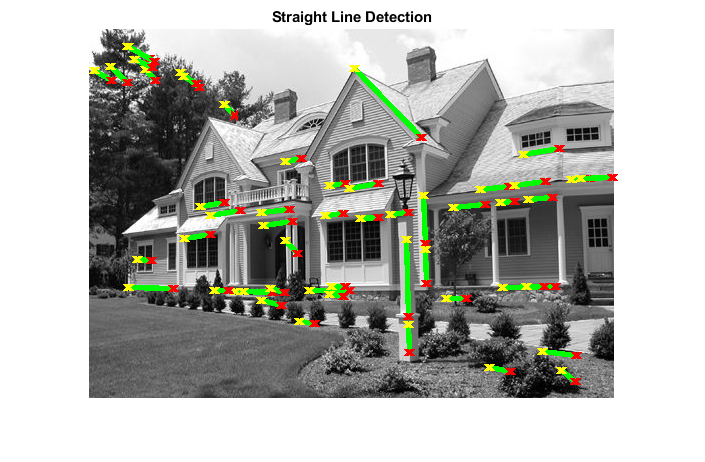

numPeaks = 30; 
[H, theta, rho] = hough(BW_1);
peaks = houghpeaks(H, numPeaks, 'Threshold', ceil(0.3*max(H(:))));
xPeaks = theta(peaks(:,2));
yPeaks = rho(peaks(:,1));
lines = houghlines(BW, theta, rho, peaks, 'FillGap', 5, 'MinLength', 14);

figure, imshow(Img), title('Straight Line Detection'), hold on;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 4, 'Color', 'green');
    plot(xy(1,1), xy(1,2), 'x', 'LineWidth', 4, 'Color', 'yellow');
    plot(xy(2,1), xy(2,2), 'x', 'LineWidth', 4, 'Color', 'red');
end

**a) What does a specific position in the Hough space correspond to in the image?**

Represents a possible staright line in the image.

**b) Which lines did you detect in the end? Show the image with detected lines plotted.**

From the above image the detected lines are the major structural lines such as the roof, walls, windows, doors and some smaller edges 

**c) How noisy (i.e. broken) do the edges have to be before Hough is unable to detect the original geometric structure in the image?**

Hough works well when edges are continuous and aligned to a straight-line model. The edge gaps have to be too large, when high-gradient pixels are there and no curved line should be dominate.

**Problem 2: FFT Transform (10 points): Produce three simple images consisting of a single edge, a box, and a rotated box (by 45 degrees), respectively, like the three images shown below: For each image, calculate the Fourier Transform (FT) and shift it such that the DC coefficient will be placed in the center. Display the spectrum of the transform for each of the image. Briefly describe the FT images and the relationship among them, if any. Note: The spectrum is the magnitude of the Fourier transform. In general, the spectrum has large values, so in order to display it some transformations might be necessary (see the class notes).**

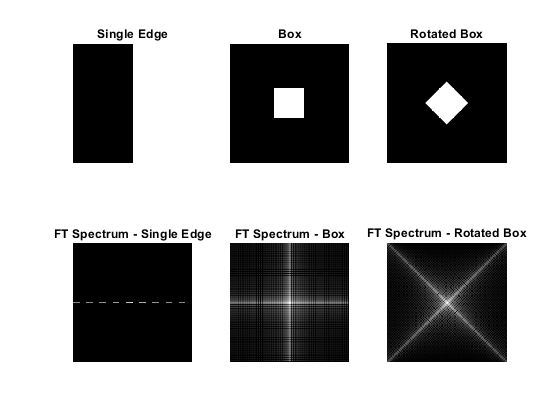

single_edge = zeros(256,256);
single_edge(:, 129:end) = 1; 

Box = zeros(256,256);
Box(96:160, 96:160) = 1; 

Rotated_box = imrotate(Box, 45, 'bilinear', 'crop');  
FT1 = fftshift(fft2(single_edge));
FT2 = fftshift(fft2(Box));
FT3 = fftshift(fft2(Rotated_box));

S1 = log(1 + abs(FT1));
S2 = log(1 + abs(FT2));
S3 = log(1 + abs(FT3));

figure;
subplot(2,3,1), imshow(single_edge, []), title('Single Edge');
subplot(2,3,2), imshow(Box, []), title('Box');
subplot(2,3,3), imshow(Rotated_box, []), title('Rotated Box');
subplot(2,3,4), imshow(S1, []), title('FT Spectrum - Single Edge');
subplot(2,3,5), imshow(S2, []), title('FT Spectrum - Box');
subplot(2,3,6), imshow(S3, []), title('FT Spectrum - Rotated Box');

**Problem 3 (10 points): Gaussian Filtering in the frequency domain: Create a Gaussian filter (‘fspecial.m’), multiply it (‘.*’ operator in Matlab) by the Fourier Transform of the ‘cameraman’ image (found on D2L), and invert the result (‘ifft2.m’). Show the images for the Gaussian low-pass filter in the frequency domain and the resulting filtered images for  equal to 10 and 30. Briefly describe the differences between the filters and the filtered images for different values of sigma (sigma is the standard deviation that controls the size of the filter).**

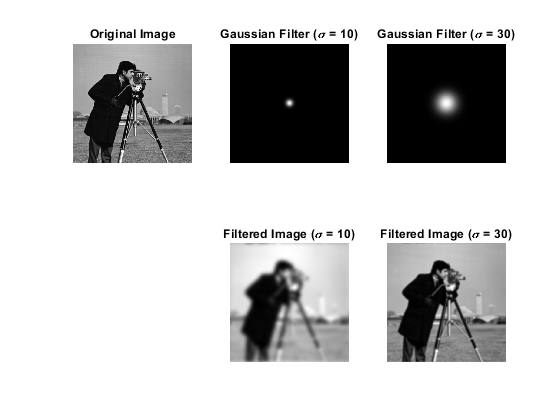

Img = imread('C:\\Users\\PVENUGO1\\Downloads\\APPLIED IMAGE ANALYSIS - 2222025 - 1125 PM\\cameraman.tif');
Img = im2double(Img); 
[length, breadth] = size(Img);

FT_Img = fftshift(fft2(Img));
s1 = 10;
s2 = 30;

H1 = fspecial('gaussian', [length breadth], s1);
H2 = fspecial('gaussian', [length breadth], s2);

FT_filtered1 = FT_Img .* H1;
FT_filtered2 = FT_Img .* H2;
filtered_Img_1 = abs(ifft2(ifftshift(FT_filtered1)));
filtered_Img_2 = abs(ifft2(ifftshift(FT_filtered2)));

figure;
subplot(2,3,1), imshow(Img, []), title('Original Image');
subplot(2,3,2), imshow(H1, []), title('Gaussian Filter (\sigma = 10)');
subplot(2,3,3), imshow(H2, []), title('Gaussian Filter (\sigma = 30)');
subplot(2,3,5), imshow(filtered_Img_1, []), title('Filtered Image (\sigma = 10)');
subplot(2,3,6), imshow(filtered_Img_2, []), title('Filtered Image (\sigma = 30)');

**Difference between Gaussian Filter:**

The filter with σ=10 is more compact, concentrated at the center and allows more high-frequency components to pass by preserving more details in the image.

The filter with σ=30 is wider and removes more high-frequency components, resulting in a stronger blurring effect.

**Difference between Filtered Images:**

The image with σ=10 is slightly blurred, where fine details are still visible, but edges are softened.

The image with σ=30 is heavily blurred, removing sharp edges and much smoother appearance.